# Universidad del Cauca - 2021.1

# Teoria de las telecomunicaciones

## Trabajo 1 - Grupo A12 - Nicolás Chicaiza y Nicolás Zambrano

### Script de automatización de sumatoria para la serie de Fourier

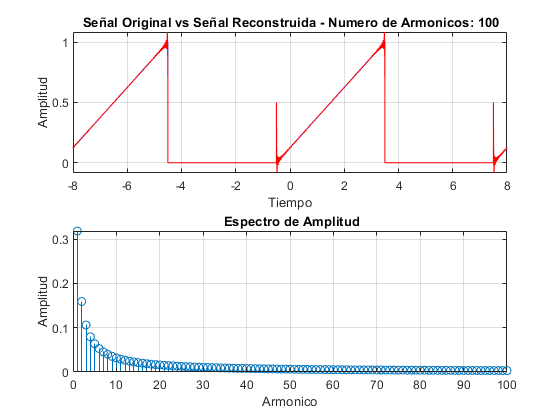

clear %Limpio Espacio de trabajo
clc
narm=100; %Numero de armonicos tomados para reconstruir la señal
A=1; %Amplitud
T=4; %Periodo
f=1/T; %Frecuencia
np=T*0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)
dds=(A/2)*(sawtooth((t+0.5)*(2*pi)/T)+1); %Funcion de referencia ¨Diente de sierra original¨
cuadrada=(A/2)*(square(pi*(t+0.5)/T)+1); %Función de referencia "Cuadrada"
resul=dds.*cuadrada;
ao=(A)*(1/2); %Inicializo valores de Serie de Fourier (A0)*(1/2)
%an=0 para cualquier n>0
Sefu=ao;
for n=1:narm %Ciclo de sumatoria (desde n=1 hasta el numero de armonicos deseados (narm))
    wn(n)=(2*pi*n*f);
    bn=sin(wn(n)*(t+1/2));    
    cbn(n)=-(A)/(pi*n);
    Sefu=Sefu+(cbn(n)*bn);
end
subplot(2,1,1)
plot(t,resul,'b',t,Sefu.*cuadrada,'r'),hold on, grid on,xlabel Tiempo, ylabel Amplitud; %Graficacion de Resultados
title(['\bf Señal Original vs Señal Reconstruida - Numero de Armonicos: ',num2str(n),'']);
subplot(2,1,2)
stem(-cbn),grid on,xlabel Armonico, ylabel Amplitud; %Graficacion de Resultados
title('\bf Espectro de Amplitud');